# Lab 4 – Noise and Filtering

Course: Mathematical Algorithms (DSP)

**Lecture: 9 – Image Processing LabsObjective**

The objective of this lab is to understand how different types of noise affect digital images and how filtering techniques can reduce their effects.

Gaussian noise and salt-and-pepper noise are added to a grayscale image. Mean, Gaussian, and median filters are then applied to compare their effectiveness.

The quality of the images is evaluated using Mean Square Error (MSE) and Signal-to-Noise Ratio (SNR).

The lab also examines the differences between linear and nonlinear filtering and how they affect image details.

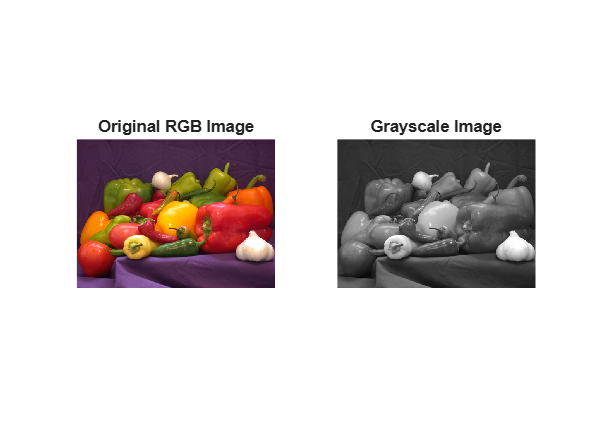


%% Lab 4: Noise and Filtering
% Section 0: Load and Prepare the Image

close all;
clear;
clc;

% Load the original image
I0 = imread('peppers.png');

% Convert to grayscale and double precision
I = im2double(rgb2gray(I0));

% Display original and grayscale images
figure;

subplot(1,2,1);
imshow(I0);
title('Original RGB Image');

subplot(1,2,2);
imshow(I);
title('Grayscale Image');


% Display image information
[M, N] = size(I);

fprintf('Image size: %d x %d\n', M, N);

Image size: 384 x 512


fprintf('Data type: %s\n', class(I));

Data type: double


fprintf('Intensity range: %.3f to %.3f\n', ...
    min(I(:)), max(I(:)));

Intensity range: 0.031 to 1.000


**Section 0 – Image Preparation**

The original `peppers.png` image was loaded into MATLAB and converted from RGB to grayscale using `rgb2gray`.

The grayscale image was then converted to double precision using `im2double`, with pixel intensities represented between 0 and 1.

The image dimensions and intensity range were checked to confirm that the image was ready for processing.

This grayscale image will be used as the reference for adding noise, applying filters, and evaluating image quality.

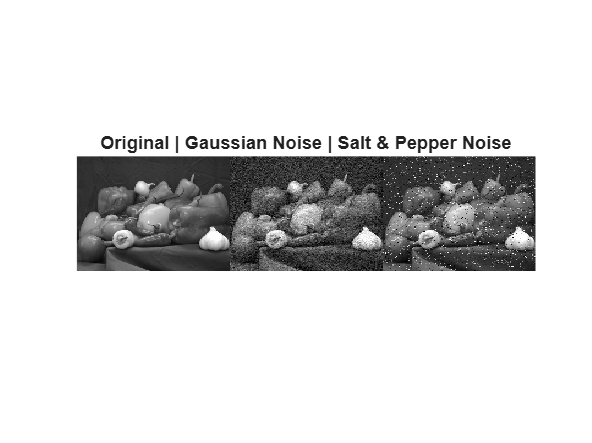


%% 1) Add Different Noise Types

% Add Gaussian noise
% Mean = 0, Variance = 0.01
I_gauss = imnoise(I, 'gaussian', 0, 0.01);

% Add salt-and-pepper noise
% Noise density = 0.05 (5%)
I_sp = imnoise(I, 'salt & pepper', 0.05);

% Display original and noisy images
figure;

montage({I, I_gauss, I_sp}, 'Size', [1 3]);

title('Original | Gaussian Noise | Salt & Pepper Noise');

**Section 1 – Adding Different Noise Types**

Two types of noise were added to the original grayscale image using the MATLAB `imnoise` function.

Gaussian noise was generated with a mean of 0 and a variance of 0.01. This introduces random intensity variations across the image, giving it a grainy appearance.

Salt-and-pepper noise was generated with a density of 0.05, meaning approximately 5% of the image pixels were randomly changed to black or white.

The Gaussian noise affects pixel intensities throughout the image, while salt-and-pepper noise creates isolated extreme pixel values.

This experiment demonstrates that different noise types produce different visual effects and may require different filtering techniques.


%% 2) Compute Image Quality Metrics

% Calculate Mean Square Error (MSE)
MSE_gauss = immse(I_gauss, I);
MSE_sp = immse(I_sp, I);

% Display MSE results
fprintf('MSE Gaussian: %.4f | MSE S&P: %.4f\n', ...
    MSE_gauss, MSE_sp);

MSE Gaussian: 0.0096 | MSE S&P: 0.0158



% Calculate signal power
signal_power = mean(I(:).^2);

% Calculate Signal-to-Noise Ratio (SNR) in dB
SNR_gauss = 10 * log10(signal_power / MSE_gauss);
SNR_sp = 10 * log10(signal_power / MSE_sp);

% Display SNR results
fprintf('SNR Gaussian: %.2f dB\n', SNR_gauss);

SNR Gaussian: 11.51 dB


fprintf('SNR Salt & Pepper: %.2f dB\n', SNR_sp);

SNR Salt & Pepper: 9.34 dB


**Section 2 – Image Quality Metrics**

The Mean Square Error (MSE) was calculated to measure the difference between the original image and the images containing Gaussian and salt-and-pepper noise.

MSE represents the average squared difference between corresponding pixel values. A lower MSE indicates that the noisy image is closer to the original image.

The Signal-to-Noise Ratio (SNR) was also calculated in decibels by comparing the original image's signal power with the noise power.

A higher SNR indicates better image quality because the signal is stronger relative to the noise.

These measurements provide a numerical way to compare the effects of different noise types and will help evaluate the filtering results in the following sections.

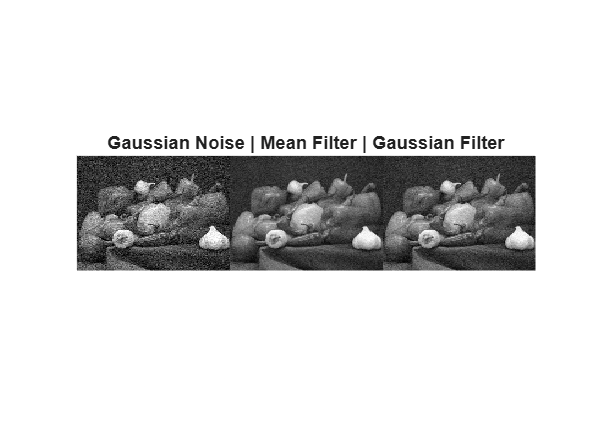


%% 3) Linear Filtering (Mean and Gaussian)

% Create a 3x3 mean filter
h_avg = fspecial('average', 3);

% Apply mean filter to Gaussian noisy image
I_avg_gauss = imfilter(I_gauss, h_avg, 'replicate');

% Apply mean filter to salt-and-pepper noisy image
I_avg_sp = imfilter(I_sp, h_avg, 'replicate');

% Create a 3x3 Gaussian filter
h_gauss = fspecial('gaussian', [3 3], 0.7);

% Apply Gaussian filter to Gaussian noisy image
I_gauss_gauss = imfilter(I_gauss, h_gauss, 'replicate');

% Display results for comparison
figure;

montage({I_gauss, I_avg_gauss, I_gauss_gauss}, ...
    'Size', [1 3]);

title('Gaussian Noise | Mean Filter | Gaussian Filter');

**Section 3 – Linear Filtering (Mean and Gaussian)**

Two linear filtering techniques were applied to reduce image noise: mean filtering and Gaussian filtering.

A 3×3 mean filter was created using `fspecial('average', 3)` and applied to both Gaussian and salt-and-pepper noisy images. The mean filter reduces noise by averaging neighboring pixel intensities, although it can also blur edges and fine image details.

A 3×3 Gaussian filter with a standard deviation of 0.7 was also created and applied to the Gaussian noisy image. Unlike the mean filter, the Gaussian filter assigns greater weights to pixels near the center of the kernel.

The filtering results illustrate how local averaging can reduce random intensity variations while also affecting image sharpness.

The `replicate` boundary option was used to handle pixels near the image edges.

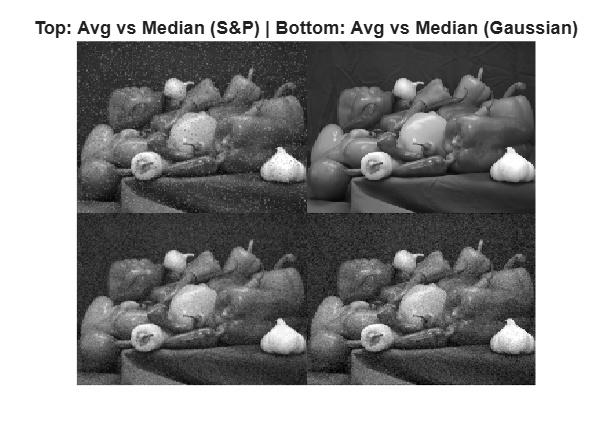


%% 4) Nonlinear Filtering (Median)

% Apply 3x3 median filter to Gaussian noisy image
I_med_gauss = medfilt2(I_gauss, [3 3]);

% Apply 3x3 median filter to salt-and-pepper noisy image
I_med_sp = medfilt2(I_sp, [3 3]);

% Compare mean and median filtering
figure;

montage({I_avg_sp, I_med_sp, ...
    I_avg_gauss, I_med_gauss}, 'Size', [2 2]);

title('Top: Avg vs Median (S&P) | Bottom: Avg vs Median (Gaussian)');

**Section 4 – Nonlinear Filtering (Median Filter)**

A 3×3 median filter was applied to both the Gaussian noisy image and the salt-and-pepper noisy image using the MATLAB `medfilt2` function.

Unlike the mean filter, which calculates the average of neighboring pixels, the median filter replaces each pixel with the median intensity value within its neighborhood.

Median filtering is particularly effective for salt-and-pepper noise because it can remove isolated extreme pixel values without spreading their influence across neighboring pixels.

The mean and median filtering results were displayed in a 2×2 comparison figure for both noise types.

This experiment demonstrates how nonlinear filtering can reduce impulse noise while often preserving image edges better than simple averaging.


%% 5) Compare Metrics After Filtering

% Calculate MSE after filtering salt-and-pepper noise
MSE_avg_sp = immse(I_avg_sp, I);
MSE_med_sp = immse(I_med_sp, I);

% Display the lecturer's requested results
fprintf('After filtering, MSE S&P avg=%.4f, med=%.4f\n', ...
    MSE_avg_sp, MSE_med_sp);

After filtering, MSE S&P avg=0.0021, med=0.0001



% Compare with the original noisy image
fprintf('\nSalt-and-Pepper Noise Comparison:\n');


Salt-and-Pepper Noise Comparison:


fprintf('Before filtering: %.4f\n', MSE_sp);

Before filtering: 0.0158


fprintf('After mean filter: %.4f\n', MSE_avg_sp);

After mean filter: 0.0021


fprintf('After median filter: %.4f\n', MSE_med_sp);

After median filter: 0.0001


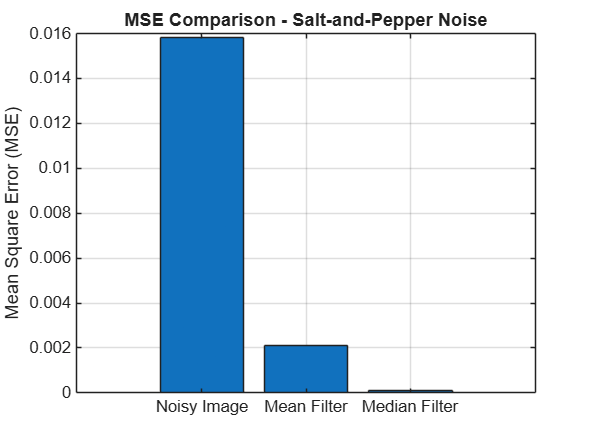


% Display MSE comparison as a bar chart
figure;

MSE_values = [MSE_sp, MSE_avg_sp, MSE_med_sp];

bar(MSE_values);

set(gca, 'XTickLabel', ...
    {'Noisy Image', 'Mean Filter', 'Median Filter'});

ylabel('Mean Square Error (MSE)');
title('MSE Comparison - Salt-and-Pepper Noise');
grid on;

**Section 5 – Comparing MSE After Filtering**

The Mean Square Error (MSE) was calculated to evaluate the performance of the mean and median filters on the salt-and-pepper noisy image.

The MSE values were compared with the original noisy image to determine how much each filtering method reduced the error.

A lower MSE indicates that the filtered image is closer to the original image.

Median filtering is generally more effective for salt-and-pepper noise because it removes isolated extreme pixel values without spreading their influence to neighboring pixels.

The comparison demonstrates how MSE can be used to evaluate image filtering performance numerically, alongside visual inspection of the filtered images.

## Section 6 – Reflections

**1. Which noise is best removed by the median filter? Why?**

The median filter is particularly effective at removing salt-and-pepper noise.

This type of noise creates isolated black and white pixels with extreme intensity values. The median filter replaces each pixel with the median value of its neighboring pixels, which helps remove these extreme values without significantly affecting the surrounding image.

Unlike the mean filter, the median filter does not average the extreme noise values with neighboring pixels.

As a result, median filtering usually removes salt-and-pepper noise more effectively while preserving image edges and details.

**2. Why does linear filtering blur edges more?**

Linear filters, such as mean and Gaussian filters, reduce noise by calculating weighted averages of neighboring pixel values.

However, image edges represent sudden changes in intensity. When a linear filter averages pixels from both sides of an edge, the intensity difference becomes smaller, making the edge appear blurred.

The mean filter gives equal weight to all pixels in its neighborhood, while the Gaussian filter gives greater weight to pixels near the center.

Both methods can reduce noise, but they may also smooth important image details.

**3. How could we design adaptive filters to preserve detail?**

Adaptive filters could be designed to adjust their filtering strength according to the local characteristics of the image.

For example, a filter could apply stronger smoothing in uniform regions where noise is more noticeable and weaker smoothing near edges or detailed areas.

Local variance or edge detection could be used to identify areas that contain important image structures.

An adaptive median filter could also change its neighborhood size depending on the amount of impulse noise.

These approaches could help reduce noise while preserving edges, textures, and fine details.